% (C) Copyright 2011-2025 DQ Robotics Developers
% 
% This file is part of DQ Robotics.
% 
%     DQ Robotics is free software: you can redistribute it and/or modify
%     it under the terms of the GNU Lesser General Public License as published by
%     the Free Software Foundation, either version 3 of the License or
%     (at your option) any later version.
% 
%     DQ Robotics is distributed in the hope that it will be useful,
%     but WITHOUT ANY WARRANTY; without even the implied warranty of
%     MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the
%     GNU Lesser General Public License for more details.
% 
%     You should have received a copy of the GNU Lesser General Public License
%     along with DQ Robotics.  If not, see <http://www.gnu.org/licenses/>.
%
% DQ Robotics website: dqrobotics.github.io
%
% Contributors to this file:
%     Frederico Fernandes Afonso Silva (frederico.silva@ieee.org)
clear all; %#ok
close all;
clc

# Static world (part 1)

## Introduction

Now that we know how to interact with robots in CoppeliaSim, we will start to actuate on the robot through the MATLAB interface. Before we start, again, let us add the namespace to our workspace. 

%% Include the DQ Robotics namespace. Probably a good idea to add to all scripts.
include_namespace_dq

Please remember that MATLAB allows you to run this file section by section (Ctrl + Enter shortcut) if you want to follow this tutorial step by step.

Now, let us open the scene that we have used before [static_world.ttt]. You should see something similar to the image below.

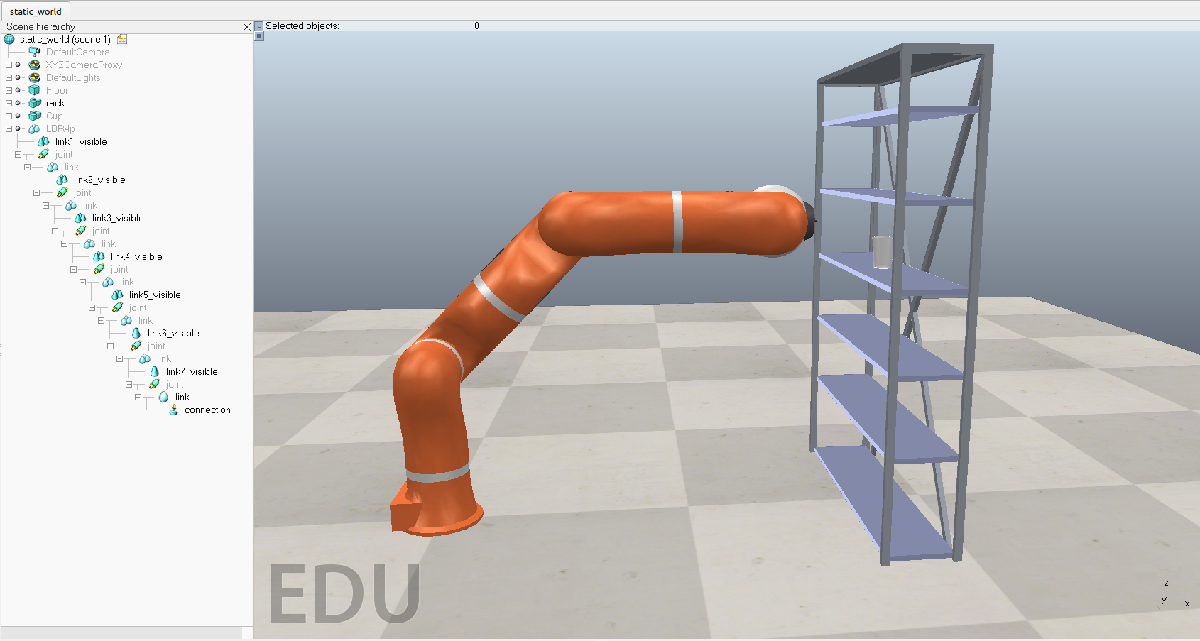

## Communicating with CoppeliaSim

We always start by establishing communication with CoppeliaSim. We first create a 'DQ_CoppeliaSimInterfaceZMQ' object,

cs = DQ_CoppeliaSimInterfaceZMQ();

This version of DQ_CoppeliaSimInterfaceZMQ is compatible with CoppeliaSim 4.7.0-rev4


then we stablish a new connection with CoppeliaSim.

cs.connect;

We can now start a new simulation

cs.start_simulation();

As in the previous lesson, the grayed out 'Start/resume simulation' button, as well as the running clock, indicate that the simulation is currently running (even if the robot/objects aren't moving yet!), and we are still working with dynamics disabled.

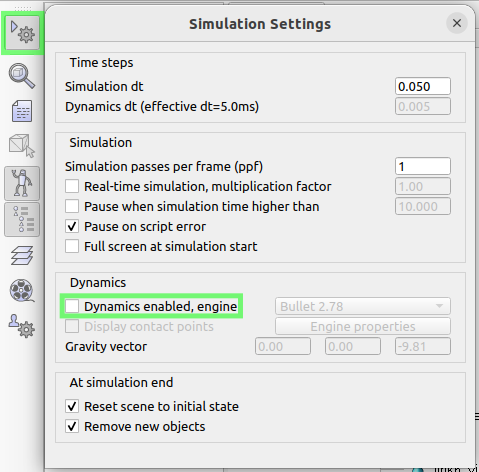

## Reading and sending joint positions (the manual way)

'DQ_CoppeliaSimInterfaceZMQ' allows us to get the joint positions of a robot in the CoppeliaSim scene. For instance, we can get the current position of the first joint of the KUKA LBR4+ robotic manipulator.

jointname={'/LBR4p/joint'};
cs.get_joint_positions(jointname)

ans = 0

We can also send joint positions to the robot. With the dynamics disabled in the [static_world.ttt], the only way to do it is by directly setting a joint configuration in CoppeliaSim. For instance, if you have been running this tutorial up to here, you should see the first joint of the LBR4+ at configuration zero.

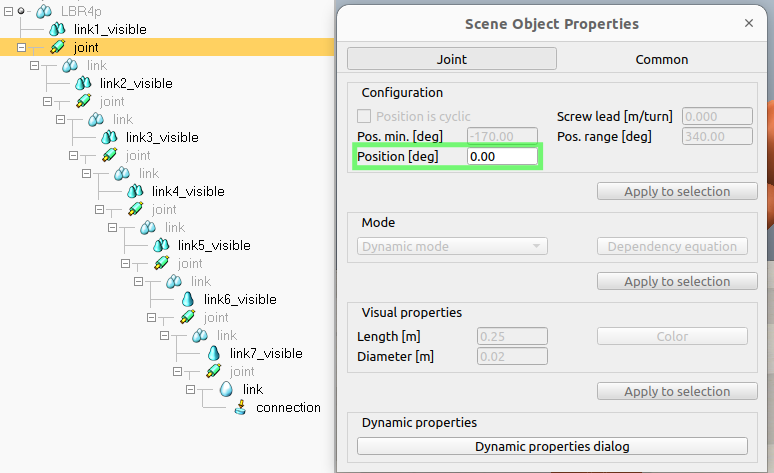

We can set it to $\frac{\pi }{2}$ rad,

q = pi/2;
cs.set_joint_positions(jointname, q);

which instantaneously brings LBR4+'s first joint to this configuration (since the internal controller dynamics are disabled!). Notice that CoppeliaSim displays angle information in degrees rather than radians.

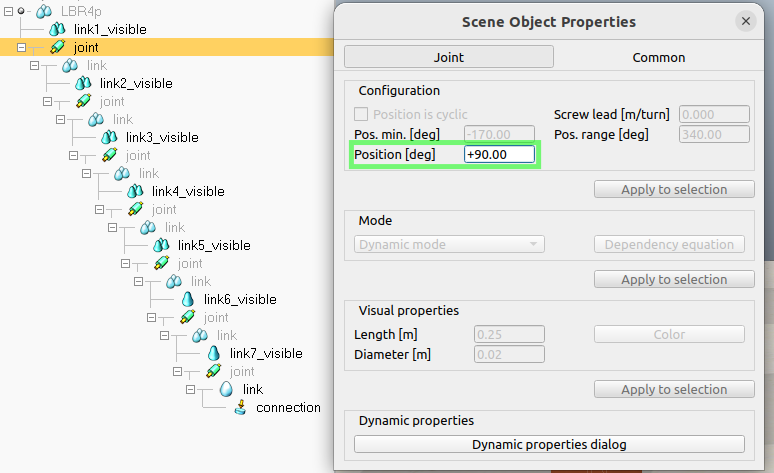

## Reading and sending joint positions using the robot's class

Reading and sending information to each joint of a robot individually, as we did in the previous section, becomes rather tedious in no time, even for simple manipulators. That is why we rely on robot classes to communicate with CoppeliaSim! The KUKA LBR4+ robotic manipulator has one already implemented, which you can check using MATLAB's help function.

help LBR4pVrepRobot

  CLASS LBR4pVrepRobot - Concrete class to interface with the "KUKA LBR4+"
  robot in VREP.
 
  Usage:
        1) Drag-and-drop a "KUKA LBR4+" robot to a VREP scene.
        2) Run
            >> vi = DQ_VrepInterface();
            >> vi.connect('127.0.0.1',19997);
            >> vrep_robot = LBR4pVrepRobot("LBR4p", vi);
            >> vi.start_simulation();
            >> robot.get_q_from_vrep();
            >> pause(1);
            >> vi.stop_simulation();
            >> vi.disconnect();
        Note that the name of the robot should be EXACTLY the same as in
        VREP. For instance, if you drag-and-drop a second robot, its name
        will become "LBR4p#0", a third robot, "LBR4p#1", and so on.
 
    LBR4pVrepRobot Methods:
        send_q_to_vrep - Sends the joint configurations to VREP
        get_q_from_vrep - Obtains the joint configurations from VREP
        kine

We intend to add more robot classes to the library in the future, but it is likely that you will have to implement one yourself at some point. Feel free to use the [existing ones](https://github.com/dqrobotics/matlab/tree/master/interfaces/vrep/robots) as models!

Using the 'LBR4pVrepRobot' class we can read the current joint configurations of the LBR4+ robot,

vrep_robot = LBR4pVrepRobot("LBR4p", vi);
vrep_robot.get_q_from_vrep;

and send it to its initial configuration.

q = [0, 0, 0, 0, 0, 0, 0];
vrep_robot.send_q_to_vrep(q);

All of that without having to think about the joint aliases!

## Finishing communication with CoppeliaSim

After finishing the simulation, we can end the communication with CoppeliaSim.

cs.stop_simulation();

# Homework

- Save the [static_world.ttt] scene as [static_world_part2_homework.ttt] and, in it, do 2-7.

- Add a KUKA LBR iiwa 7 R800 to the scene.

- Move it to position [2.000; 0.000; 0.07875].

- Read its joint configurations.

- Set its joints to [0; -$\frac{\pi }{4}$; 0; $\frac{\pi }{4}$; $\frac{\pi }{2}$; 0; 0].

- Bonus: based on 'LBR4pVrepRobot', create a class for the KUKA LBR iiwa 7 R800 manipulator and do 4-5 using it.

- Bonus: get the end-effector pose ('connection') of the KUKA LBR iiwa 7 R800 manipulator.